% Put your data file name here. Possible names are:
%% 90CCW_180CW
%% 90CCW
%% 90CW
clear all;
filename = '90CCW';

fig=gcf;
fig.Position(4)=550;

data = load(filename+".mat");
m = data.MagneticField;
a = data.AngularVelocity;
o = data.Orientation;
a_data = [a.X, a.Y, a.Z];
m_data = [m.X, m.Y, m.Z];
o_data = [o.X, o.Y, o.Z];

% Sampling frequency
f=10;

% Discontinuity threshold in degrees
thresh = 350;

t = a.Timestamp.Second - a.Timestamp.Second(1);
t(t<0) = t(t<0) + 60;

% Create directory to store results
if ~exist(filename, 'dir')
   mkdir(filename)
end

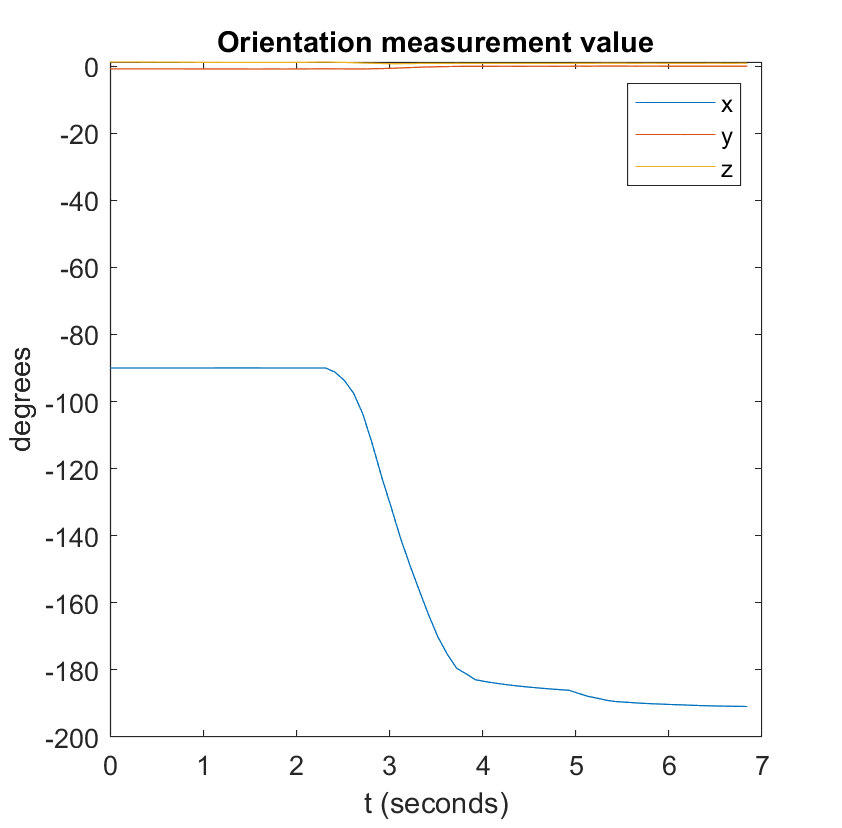


% Plot orientation
truth = unwrap(o.X,thresh);
plot(t,unwrap(o_data,thresh));
legend('x','y','z');
title('Orientation measurement value');
xlabel('t (seconds)');
ylabel('degrees');
print(append(filename,'/orientation_truth.png'),'-dpng');

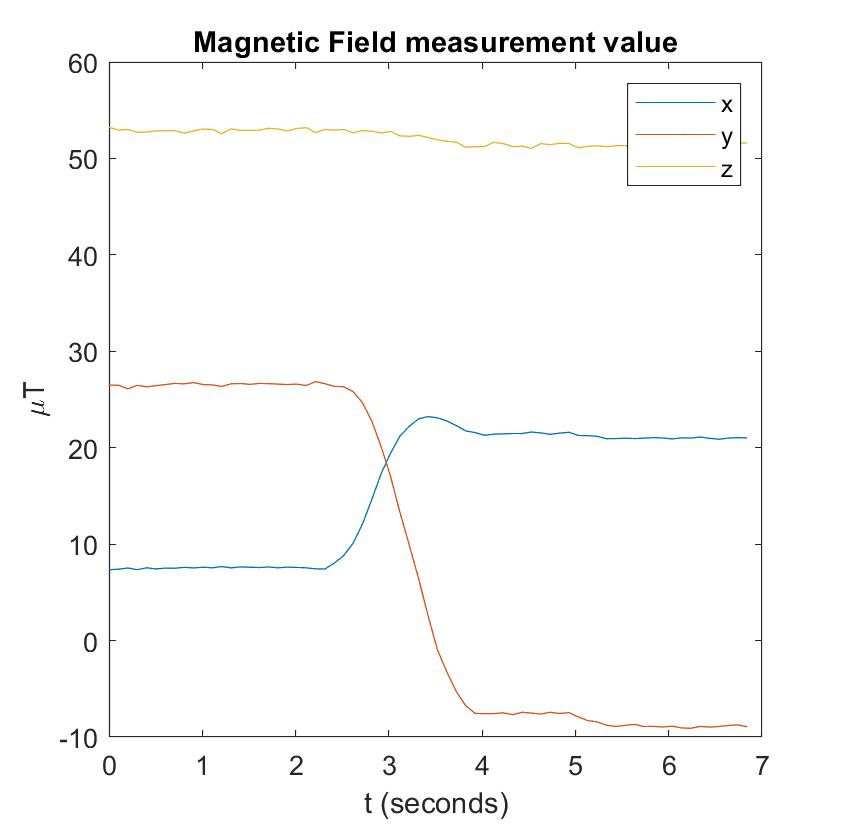


% Plot magnetic field
plot(t,m_data);
legend('x','y','z');
title('Magnetic Field measurement value');
xlabel('t (seconds)');
ylabel('\muT');

%print(append(filename,'/magnetic_value.png'),'-dpng');

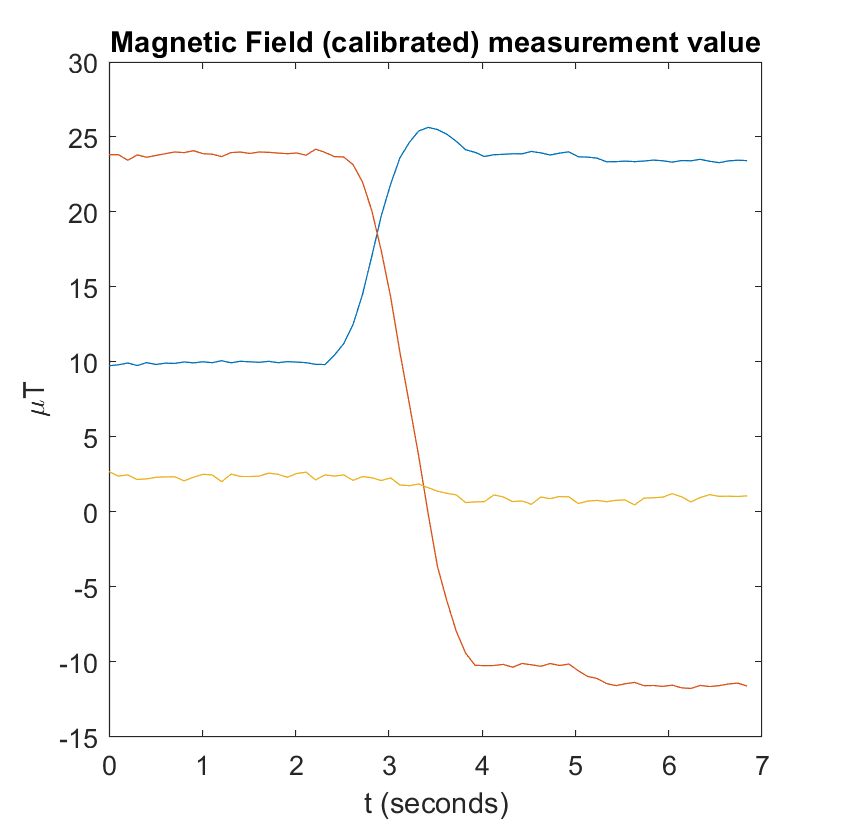

% Magnetometer calibration
[A,b,~]  = magcal(m_data);
M = (m_data-b)*A;
plot(t,M);
title('Magnetic Field (calibrated) measurement value');
xlabel('t (seconds)');
ylabel('\muT');
print(append(filename,'/magnetic_value.png'),'-dpng');

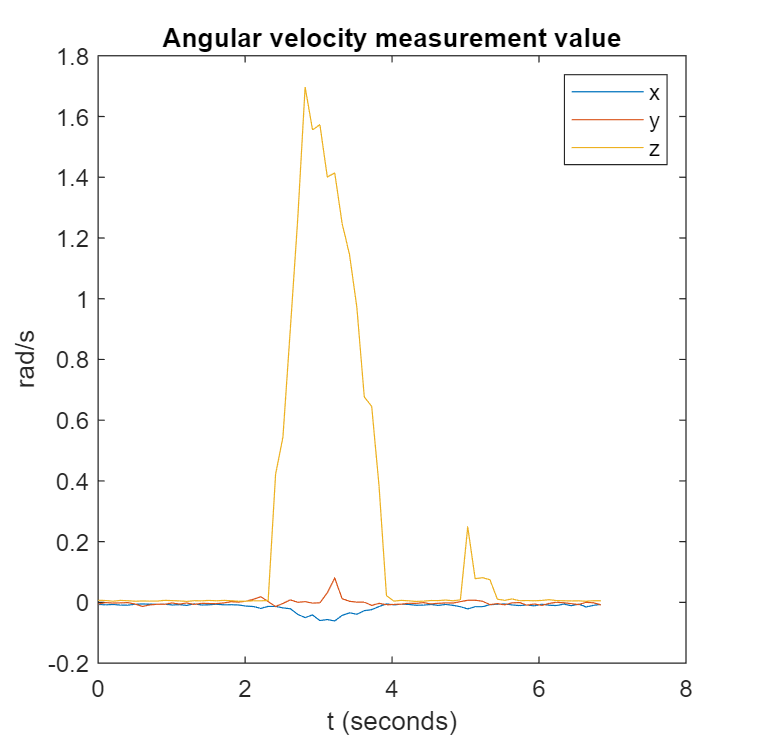


% Plot angular velocity
plot(t,a_data);
legend('x','y','z');
title('Angular velocity measurement value');
xlabel('t (seconds)');
ylabel('rad/s');
print(append(filename,'/angular_velo_value.png'),'-dpng');

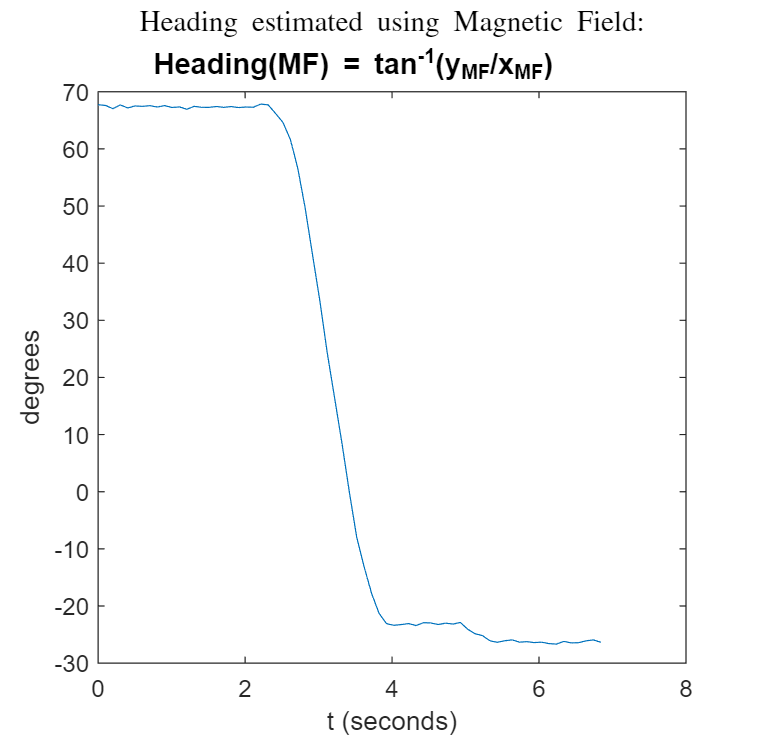


% Plot heading estimation using magnetic field
dm = rad2deg(atan2(M(:,2),M(:,1)));
mf_est = unwrap(dm,thresh);
plot(t,mf_est);
title('Heading estimated using Magnetic Field:\newline Heading(MF) = tan^{-1}(y_{MF}/x_{MF})','FontSize',12);
xlabel('t (seconds)');
ylabel('degrees');
print(append(filename,'/magnetic_estimation.png'),'-dpng');

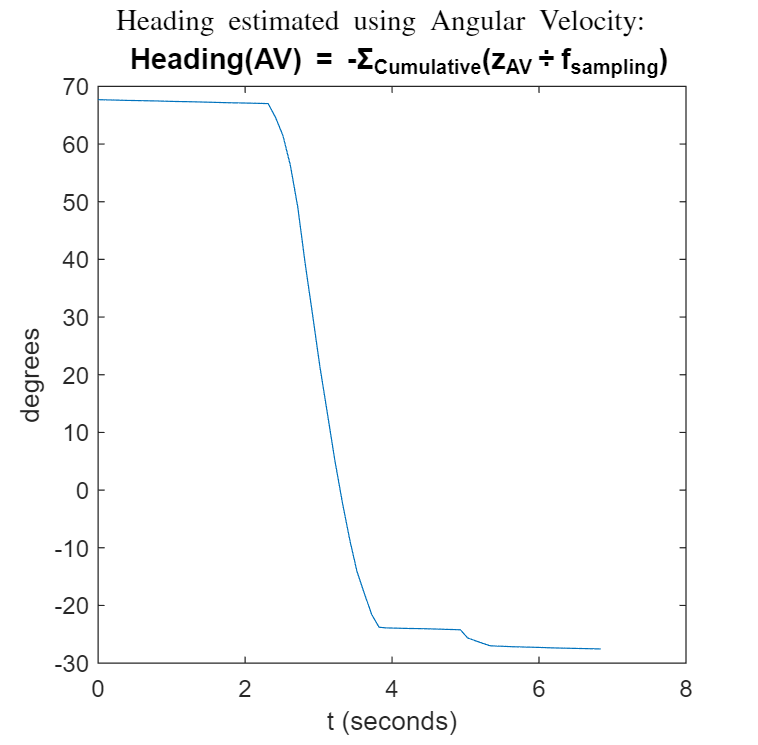


% Plot heading estimation using angular velocity
da = rad2deg(cumsum(-a.Z/f));
av_est = da+dm(1);
plot(t,av_est);
title('Heading estimated using Angular Velocity:\newline Heading(AV) = -\Sigma_{Cumulative}(z_{AV}\divf_{sampling})','FontSize',12);
xlabel('t (seconds)');
ylabel('degrees');
print(append(filename,'/angular_velo_estimation.png'),'-dpng');

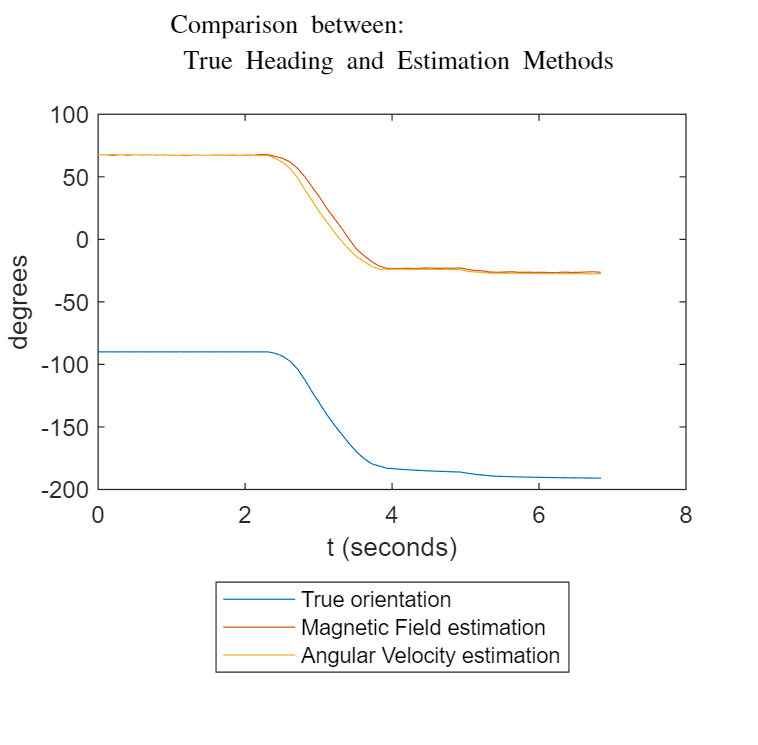


% Comparison plot
plot(t,[truth, mf_est, av_est]);
legend('True orientation','Magnetic Field estimation','Angular Velocity estimation','location','southoutside');
title('Comparison between:\newline True Heading and Estimation Methods\newline');
xlabel('t (seconds)');
ylabel('degrees');
print(append(filename,'/estimation_comparison.png'),'-dpng');